fprintf("CS205 Project 1");

CS205 Project 1


%note: this project is designed to be similar to the CS170 8 tile puzzle solver
%project, thus alot of the code here will look similar to my implementation
%of it

%define the map matrix that is the Trench
%it is defined as the win condition
%the 0 is the blank space
problem = [
    -1,-1,-1, 0,-1, 0, -1, 0, -1, -1;
     0, 2, 2, 2, 2, 2,  2, 2,  2,  1]

problem =     -1    -1    -1     0    -1     0    -1     0    -1    -1
     0     2     2     2     2     2     2     2     2     1


 
 solution = [
    -1,-1,-1, 0,-1, 0, -1, 0, -1, -1;
     1, 2, 2, 2, 2, 2,  2, 2,  2,  0]

solution =     -1    -1    -1     0    -1     0    -1     0    -1    -1
     1     2     2     2     2     2     2     2     2     0



%concatenated to the right of each matrix is the additional information
% 0 indicates a space that is empty and can be moved into by any trench men
% 1 indicates the trench officer and must be moved to the leftmost tile
% 2 indicates the other non-officer trench men
%-1 indicates an obstacle. these tiles cannot be moved into
% top right '0' will indicate weight of the node

%i will not create the code that randomly generates a combination of the
%puzzle, because it may not be in the parity needed to reach the solution,
%starting states can be input manually.
%i make the assumption a solution exists for the input initial state

%if the depth of the problem is known, 
% we can use it for depth limitedearchs
%depth = 4

%this is the enumerator that will define the queueing function used by the
%algorithm
% 0-- Uniform Cost search
% 1-- A* with Misplaced Tile Heuristic
% 2-- A* with Manhattan Distance Hueristic

%note that Uniform Cost will be the default for input outside these values
QUEUEING_FUNCTION = 0;

%nodes is a 3D array representing the queue of matrix states 
%   nodes(:,:,1) = node with least weight / closest to solution
%when appending a new node:
%   nodes(:,:,size(nodes,3)+1) = solution
%to sort this queue by path weight:
%   [~,SortOrder] = sort(weights),3)
%   node(:,:,SortOrder)

%if you know how deep the answer is, make it a parameter as to avoid longer
%runtime than neccessary, useful for testing, enter 0 if unknown
max_depth = 0;

%execute the general search function derived from given psuedocode
colors = ['r-','g-','b-'];

for qf = [3,1,2]
    QUEUEING_FUNCTION = qf;

    for i = 1:11%1:(size(problems,3)-2*(3-qf))
        tic;
        general_search(problems(:,:,i), solution, QUEUEING_FUNCTION,max_depth);
        data(i,:,qf) =[i,toc];
    end

    semilogy(data(:,1,qf),data(:,2,qf), colors(qf), 'LineWidth', 1, 'MarkerSize', 2);
    hold on;

end

legend('Uniform Cost Search', 'A* with Misplaced Tile', 'A* with Manhattan Distance' )
title("Figure 4: Line Plot of Runtime of Different Algorithms")
xlabel('Complexity (in moves needed to solve)');
ylabel('Time Taken to Solve (sec)')
hold off;

qf = 1

qf = 1

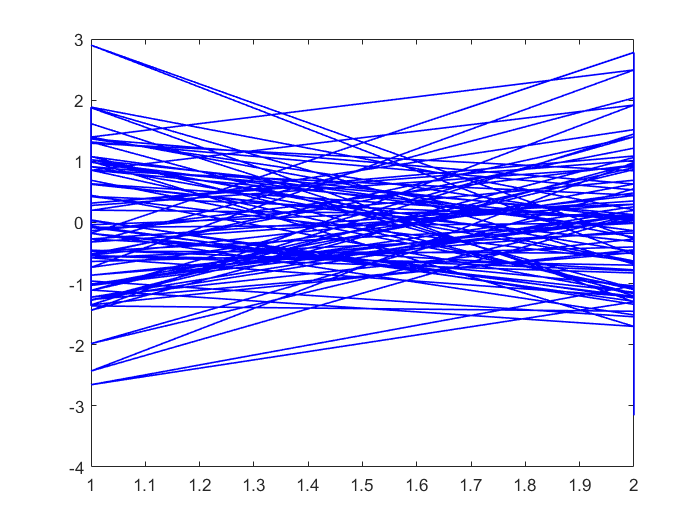

plot(data(:,1,qf),data(:,2,qf), colors(qf), 'LineWidth', 1, 'MarkerSize', 2);
hold on;

qf = 2

qf = 2

plot(data(:,1,qf),data(:,2,qf), colors(qf), 'LineWidth', 1, 'MarkerSize', 2);

Index in position 3 exceeds array bounds (must not exceed 1).

hold off;

plot(data(:,1,qf),data(:,2,qf), colors(qf), 'LineWidth', 1, 'MarkerSize', 2);
hold on;
%legend('A* with Manhattan Distance' )
title("Figure 5: Line Plot of Runtime of A* with Manhattan Distance");
xlabel('Complexity (in moves needed to solve)');
ylabel('Time Taken to Solve (sec)');
hold off;


complex_problem =      5     8     6     3
     3     7     4     2
     2     0     1    24


front_of_queue =      5     8     6     2
     3     0     4     2
     2     7     1    22


front_of_queue =      5     0     6     1
     3     8     4     2
     2     7     1    22


front_of_queue =      5     8     6     2
     0     3     4     1
     2     7     1    22


front_of_queue =      5     8     6     2
     3     4     0     3
     2     7     1    22


front_of_queue =      0     5     6     1
     3     8     4     1
     2     7     1    22


front_of_queue =      3     5     6     2
     0     8     4     1
     2     7     1    20


front_of_queue =      3     5     6     3
     2     8     4     1
     0     7     1    20


front_of_queue =      3     5     6     2
     8     0     4     2
     2     7     1    20


front_of_queue =      3     5     6     3
     2     8     4     2
     7     0     1    20


front_of_queue =      3     5     6     2
     2     0     4     2
     7     8     1    18


front_of_queue =      3     0     6     1
     2     5     4     2
     7     8     1    18


front_of_queue =      3     5     6     2
     0     2     4     1
     7     8     1    18


front_of_queue =      3     5     6     2
     2     4     0     3
     7     8     1    18


front_of_queue =      0     3     6     1
     2     5     4     1
     7     8     1    18


front_of_queue =      2     3     6     2
     0     5     4     1
     7     8     1    16


front_of_queue =      2     3     6     2
     5     0     4     2
     7     8     1    16


front_of_queue =      2     3     6     2
     5     4     0     3
     7     8     1    16


front_of_queue =      2     3     0     1
     5     4     6     3
     7     8     1    16


front_of_queue =      2     0     3     1
     5     4     6     2
     7     8     1    14


front_of_queue =      2     4     3     2
     5     0     6     2
     7     8     1    14


front_of_queue =      0     2     3     1
     5     4     6     1
     7     8     1    14


front_of_queue =      2     4     3     2
     0     5     6     1
     7     8     1    14


front_of_queue =      2     4     3     2
     5     6     0     3
     7     8     1    14


front_of_queue =      5     2     3     2
     0     4     6     1
     7     8     1    14


front_of_queue =      5     2     3     2
     4     0     6     2
     7     8     1    12


front_of_queue =      5     2     3     2
     4     6     0     3
     7     8     1    12


front_of_queue =      5     2     3     3
     4     6     1     3
     7     8     0    12


front_of_queue =      5     2     3     3
     4     6     1     2
     7     0     8    10


front_of_queue =      5     2     3     2
     4     0     1     2
     7     6     8     8


front_of_queue =      5     2     3     2
     4     1     0     3
     7     6     8     8


front_of_queue =      5     2     3     3
     4     6     1     1
     0     7     8    10


front_of_queue =      5     0     3     1
     4     2     1     2
     7     6     8    10


front_of_queue =      5     2     3     3
     4     6     1     2
     7     0     8    10


front_of_queue =      5     2     3     2
     0     4     1     1
     7     6     8    10


front_of_queue =      5     2     0     1
     4     1     3     3
     7     6     8    10


front_of_queue =      5     2     3     3
     4     1     8     3
     7     6     0    10


front_of_queue =      5     2     3     2
     0     6     1     1
     4     7     8    10


front_of_queue =      5     2     3     2
     6     0     1     2
     4     7     8     8


front_of_queue =      5     2     3     2
     6     1     0     3
     4     7     8     8


front_of_queue =      5     2     3     3
     4     6     1     2
     7     0     8    10


front_of_queue =      0     5     3     1
     4     2     1     1
     7     6     8    10


front_of_queue =      0     2     3     1
     5     4     1     1
     7     6     8    10


front_of_queue =      5     0     2     1
     4     1     3     2
     7     6     8    10


front_of_queue =      5     1     2     2
     4     0     3     2
     7     6     8     8


front_of_queue =      5     2     3     3
     4     1     8     2
     7     0     6    10


front_of_queue =      0     2     3     1
     5     6     1     1
     4     7     8    10


front_of_queue =      5     0     3     1
     6     2     1     2
     4     7     8    10


front_of_queue =      5     2     3     3
     6     7     1     2
     4     0     8    10


front_of_queue =      5     2     3     2
     0     6     1     1
     4     7     8    10


front_of_queue =      5     2     0     1
     6     1     3     3
     4     7     8    10


front_of_queue =      5     2     3     3
     6     1     8     3
     4     7     0    10


front_of_queue =      5     2     3     3
     4     6     1     1
     0     7     8    10


front_of_queue =      4     5     3     2
     0     2     1     1
     7     6     8    10


front_of_queue =      2     0     3     1
     5     4     1     2
     7     6     8    10


front_of_queue =      0     5     2     1
     4     1     3     1
     7     6     8    10


front_of_queue =      5     1     2     3
     4     6     3     2
     7     0     8    10


front_of_queue =      5     1     2     2
     0     4     3     1
     7     6     8    10


front_of_queue =      5     1     2     2
     4     3     0     3
     7     6     8    10


front_of_queue =      5     2     3     2
     4     0     8     2
     7     1     6    10


front_of_queue =      5     2     3     3
     4     1     8     1
     0     7     6    10


front_of_queue =      2     0     3     1
     5     6     1     2
     4     7     8    10


front_of_queue =      0     5     3     1
     6     2     1     1
     4     7     8    10


front_of_queue =      5     0     2     1
     6     1     3     2
     4     7     8    10


front_of_queue =      5     1     2     2
     6     0     3     2
     4     7     8     8


front_of_queue =      5     2     3     3
     6     1     8     2
     4     0     7    10


front_of_queue =      4     5     3     2
     2     0     1     2
     7     6     8    10


front_of_queue =      2     4     3     2
     5     0     1     2
     7     6     8    10


front_of_queue =      4     5     2     2
     0     1     3     1
     7     6     8    10


front_of_queue =      4     5     2     2
     1     0     3     2
     7     6     8     8


front_of_queue =      4     0     2     1
     1     5     3     2
     7     6     8     8


front_of_queue =      4     2     0     1
     1     5     3     3
     7     6     8     8


front_of_queue =      4     2     3     2
     1     5     0     3
     7     6     8     6


front_of_queue =      4     2     3     2
     1     0     5     2
     7     6     8     4


front_of_queue =      4     0     3     1
     1     2     5     2
     7     6     8     6


front_of_queue =      4     2     3     3
     1     6     5     2
     7     0     8     6


front_of_queue =      4     2     3     2
     0     1     5     1
     7     6     8     6


front_of_queue =      4     2     3     2
     1     5     0     3
     7     6     8     6


front_of_queue =      4     2     3     3
     1     6     5     1
     0     7     8     6


front_of_queue =      0     2     3     1
     4     1     5     1
     7     6     8     6


front_of_queue =      4     2     3     2
     0     6     5     1
     1     7     8     6


front_of_queue =      4     2     3     2
     6     0     5     2
     1     7     8     4


front_of_queue =      2     0     3     1
     4     1     5     2
     7     6     8     6


front_of_queue =      2     1     3     2
     4     0     5     2
     7     6     8     4


front_of_queue =      0     2     3     1
     4     6     5     1
     1     7     8     6


front_of_queue =      4     0     3     1
     6     2     5     2
     1     7     8     6


front_of_queue =      4     2     3     3
     6     7     5     2
     1     0     8     6


front_of_queue =      4     2     3     2
     0     6     5     1
     1     7     8     6


front_of_queue =      4     2     3     2
     6     5     0     3
     1     7     8     6


front_of_queue =      0     2     3     1
     4     1     5     1
     7     6     8     6


front_of_queue =      2     1     3     3
     4     6     5     2
     7     0     8     6


front_of_queue =      2     1     3     2
     0     4     5     1
     7     6     8     6


front_of_queue =      2     1     3     2
     4     5     0     3
     7     6     8     6


front_of_queue =      2     0     3     1
     4     6     5     2
     1     7     8     6


front_of_queue =      4     2     3     3
     1     6     5     1
     0     7     8     6


front_of_queue =      2     1     3     3
     4     6     5     1
     0     7     8     6


front_of_queue =      2     6     3     2
     4     0     5     2
     1     7     8     6


front_of_queue =      4     2     3     3
     1     6     5     2
     7     0     8     6


front_of_queue =      2     1     3     2
     0     6     5     1
     4     7     8     6


front_of_queue =      2     1     3     2
     6     0     5     2
     4     7     8     4


front_of_queue =      2     0     3     1
     6     1     5     2
     4     7     8     6


front_of_queue =      2     1     3     3
     6     7     5     2
     4     0     8     6


front_of_queue =      2     1     3     2
     0     6     5     1
     4     7     8     6


front_of_queue =      2     1     3     2
     6     5     0     3
     4     7     8     6


front_of_queue =      0     2     3     1
     6     1     5     1
     4     7     8     6


front_of_queue =      6     2     3     2
     0     1     5     1
     4     7     8     6


front_of_queue =      6     2     3     2
     1     0     5     2
     4     7     8     4


front_of_queue =      6     2     3     3
     4     1     5     1
     0     7     8     6


front_of_queue =      6     0     3     1
     1     2     5     2
     4     7     8     6


front_of_queue =      6     2     3     3
     1     7     5     2
     4     0     8     6


front_of_queue =      6     2     3     2
     0     1     5     1
     4     7     8     6


front_of_queue =      6     2     3     2
     1     5     0     3
     4     7     8     6


front_of_queue =      6     2     3     3
     4     1     5     2
     7     0     8     6


front_of_queue =      6     2     3     2
     4     0     5     2
     7     1     8     6


front_of_queue =      4     0     2     1
     1     5     3     2
     7     6     8     8


front_of_queue =      4     2     3     3
     1     5     8     3
     7     6     0     8


front_of_queue =      0     4     3     1
     1     2     5     1
     7     6     8     8


front_of_queue =      1     4     3     2
     0     2     5     1
     7     6     8     6


front_of_queue =      1     4     3     2
     2     0     5     2
     7     6     8     6


front_of_queue =      1     0     3     1
     2     4     5     2
     7     6     8     6


front_of_queue =      4     3     0     1
     1     2     5     3
     7     6     8     8


front_of_queue =      4     2     3     3
     1     6     5     3
     7     8     0     8


front_of_queue =      4     2     3     3
     7     1     5     1
     0     6     8     8


front_of_queue =      4     2     3     3
     7     1     5     2
     6     0     8     6


front_of_queue =      4     2     3     2
     7     0     5     2
     6     1     8     6


front_of_queue =      4     2     3     2
     0     7     5     1
     6     1     8     6


front_of_queue =      0     2     3     1
     4     7     5     1
     6     1     8     6


front_of_queue =      2     0     3     1
     4     7     5     2
     6     1     8     6


front_of_queue =      2     7     3     2
     4     0     5     2
     6     1     8     6


front_of_queue =      2     7     3     3
     4     1     5     2
     6     0     8     6


front_of_queue =      4     2     0     1
     1     5     3     3
     7     6     8     8


front_of_queue =      2     3     0     1
     4     1     5     3
     7     6     8     8


front_of_queue =      0     4     3     1
     6     2     5     1
     1     7     8     8


front_of_queue =      4     3     0     1
     6     2     5     3
     1     7     8     8


front_of_queue =      4     2     3     3
     6     7     5     1
     0     1     8     8


front_of_queue =      4     2     3     3
     6     7     5     2
     1     0     8     6


front_of_queue =      4     2     3     3
     6     7     5     3
     1     8     0     8


front_of_queue =      4     2     0     1
     6     5     3     3
     1     7     8     8


front_of_queue =      4     2     3     3
     6     5     8     3
     1     7     0     8


front_of_queue =      2     1     3     3
     4     6     5     3
     7     8     0     8


front_of_queue =      0     1     3     1
     2     4     5     1
     7     6     8     8


front_of_queue =      2     1     3     3
     7     4     5     1
     0     6     8     8


front_of_queue =      2     1     3     3
     7     4     5     2
     6     0     8     6


front_of_queue =      2     1     3     2
     7     0     5     2
     6     4     8     6


front_of_queue =      2     1     3     2
     0     7     5     1
     6     4     8     6


front_of_queue =      2     1     0     1
     4     5     3     3
     7     6     8     8


front_of_queue =      2     1     3     3
     4     5     8     3
     7     6     0     8


front_of_queue =      2     3     0     1
     4     6     5     3
     1     7     8     8


front_of_queue =      2     6     3     3
     4     7     5     2
     1     0     8     8


front_of_queue =      2     6     3     2
     0     4     5     1
     1     7     8     8


front_of_queue =      2     6     3     2
     4     5     0     3
     1     7     8     8


front_of_queue =      0     1     3     1
     2     6     5     1
     4     7     8     8


front_of_queue =      1     0     3     1
     2     6     5     2
     4     7     8     6


front_of_queue =      1     6     3     2
     2     0     5     2
     4     7     8     6


front_of_queue =      1     6     3     2
     0     2     5     1
     4     7     8     6


front_of_queue =      1     6     3     3
     4     2     5     1
     0     7     8     6


front_of_queue =      1     6     3     3
     4     2     5     2
     7     0     8     6


front_of_queue =      1     6     3     2
     4     0     5     2
     7     2     8     6


front_of_queue =      1     0     3     1
     4     6     5     2
     7     2     8     6


front_of_queue =      2     3     0     1
     6     1     5     3
     4     7     8     8


front_of_queue =      2     1     3     3
     6     7     5     1
     0     4     8     8


front_of_queue =      2     1     3     3
     6     7     5     2
     4     0     8     6


front_of_queue =      2     1     3     3
     6     7     5     3
     4     8     0     8


front_of_queue =      2     1     0     1
     6     5     3     3
     4     7     8     8


front_of_queue =      2     1     3     3
     6     5     8     3
     4     7     0     8


front_of_queue =      0     6     3     1
     1     2     5     1
     4     7     8     8


front_of_queue =      6     0     3     1
     1     2     5     2
     4     7     8     6


front_of_queue =      6     3     0     1
     1     2     5     3
     4     7     8     8


front_of_queue =      6     2     3     3
     1     7     5     1
     0     4     8     8


front_of_queue =      6     2     3     3
     1     7     5     3
     4     8     0     8


front_of_queue =      6     2     0     1
     1     5     3     3
     4     7     8     8


front_of_queue =      6     2     3     3
     1     5     8     3
     4     7     0     8


front_of_queue =      6     2     3     3
     4     1     5     3
     7     8     0     8


front_of_queue =      6     0     3     1
     4     2     5     2
     7     1     8     8


front_of_queue =      6     2     3     2
     0     4     5     1
     7     1     8     8


front_of_queue =      6     2     3     2
     4     5     0     3
     7     1     8     8


front_of_queue =      4     5     2     2
     1     0     3     2
     7     6     8     8


front_of_queue =      4     2     3     3
     1     5     8     2
     7     0     6     8


front_of_queue =      1     4     3     3
     7     2     5     1
     0     6     8     8


front_of_queue =      1     4     3     3
     7     2     5     2
     6     0     8     6


front_of_queue =      1     4     3     2
     7     0     5     2
     6     2     8     6


front_of_queue =      1     0     3     1
     7     4     5     2
     6     2     8     6


front_of_queue =      1     4     3     2
     0     7     5     1
     6     2     8     6


front_of_queue =      1     4     3     2
     7     0     5     2
     6     2     8     6


front_of_queue =      1     4     3     3
     7     2     5     2
     6     0     8     6


front_of_queue =      1     4     3     3
     2     6     5     2
     7     0     8     8


front_of_queue =      1     4     3     2
     2     5     0     3
     7     6     8     8


front_of_queue =      1     3     0     1
     2     4     5     3
     7     6     8     8


front_of_queue =      4     3     5     2
     1     2     0     3
     7     6     8     8


front_of_queue =      4     2     3     2
     1     6     0     3
     7     8     5     8


front_of_queue =      4     2     3     3
     7     1     5     3
     6     8     0     8


front_of_queue =      4     0     3     1
     7     2     5     2
     6     1     8     8


front_of_queue =      4     2     3     2
     7     5     0     3
     6     1     8     8


front_of_queue =      2     3     0     1
     4     7     5     3
     6     1     8     8


front_of_queue =      2     7     3     2
     0     4     5     1
     6     1     8     8


front_of_queue =      2     7     3     2
     4     5     0     3
     6     1     8     8


front_of_queue =      2     7     3     3
     4     1     5     1
     0     6     8     8


front_of_queue =      2     7     3     3
     4     1     5     3
     6     8     0     8


front_of_queue =      4     0     2     1
     1     5     3     2
     7     6     8     8


front_of_queue =      2     3     5     2
     4     1     0     3
     7     6     8     8


front_of_queue =      6     4     3     2
     0     2     5     1
     1     7     8     8


front_of_queue =      4     3     5     2
     6     2     0     3
     1     7     8     8


front_of_queue =      4     2     3     2
     6     7     0     3
     1     8     5     8


front_of_queue =      4     0     2     1
     6     5     3     2
     1     7     8     8


front_of_queue =      4     2     3     3
     6     5     8     2
     1     0     7     8


front_of_queue =      2     1     3     2
     4     6     0     3
     7     8     5     8


front_of_queue =      2     1     3     3
     7     4     5     3
     6     8     0     8


front_of_queue =      2     0     3     1
     7     1     5     2
     6     4     8     8


front_of_queue =      2     1     3     2
     7     5     0     3
     6     4     8     8


front_of_queue =      0     1     3     1
     2     7     5     1
     6     4     8     8


front_of_queue =      1     0     3     1
     2     7     5     2
     6     4     8     6


front_of_queue =      1     7     3     2
     2     0     5     2
     6     4     8     6


front_of_queue =      1     7     3     3
     2     4     5     2
     6     0     8     6


front_of_queue =      1     7     3     2
     0     2     5     1
     6     4     8     6


front_of_queue =      1     7     3     2
     2     0     5     2
     6     4     8     6


front_of_queue =      2     1     3     3
     6     7     5     1
     0     4     8     8


front_of_queue =      2     0     1     1
     4     5     3     2
     7     6     8     8


front_of_queue =      2     1     3     3
     4     5     8     2
     7     0     6     8


front_of_queue =      2     3     5     2
     4     6     0     3
     1     7     8     8


front_of_queue =      2     6     3     3
     1     4     5     1
     0     7     8     8


front_of_queue =      1     3     0     1
     2     6     5     3
     4     7     8     8


front_of_queue =      1     6     3     3
     2     7     5     2
     4     0     8     8


front_of_queue =      1     6     3     2
     2     5     0     3
     4     7     8     8


front_of_queue =      1     6     3     3
     4     2     5     3
     7     8     0     8


front_of_queue =      1     6     3     2
     0     4     5     1
     7     2     8     8


front_of_queue =      1     6     3     2
     4     5     0     3
     7     2     8     8


front_of_queue =      0     1     3     1
     4     6     5     1
     7     2     8     8


front_of_queue =      1     3     0     1
     4     6     5     3
     7     2     8     8


front_of_queue =      2     3     5     2
     6     1     0     3
     4     7     8     8


front_of_queue =      2     1     3     2
     6     7     0     3
     4     8     5     8


front_of_queue =      2     0     1     1
     6     5     3     2
     4     7     8     8


front_of_queue =      2     1     3     3
     6     5     8     2
     4     0     7     8


front_of_queue =      6     3     5     2
     1     2     0     3
     4     7     8     8


front_of_queue =      6     2     3     2
     0     7     5     1
     1     4     8     8


front_of_queue =      6     2     3     2
     1     7     0     3
     4     8     5     8


front_of_queue =      6     0     2     1
     1     5     3     2
     4     7     8     8


front_of_queue =      6     2     3     3
     1     5     8     2
     4     0     7     8


front_of_queue =      6     2     3     2
     4     1     0     3
     7     8     5     8


front_of_queue =      0     2     3     1
     6     4     5     1
     7     1     8     8


front_of_queue =      4     2     3     2
     1     0     8     2
     7     5     6     8


front_of_queue =      4     2     3     3
     1     5     8     1
     0     7     6     8


front_of_queue =      1     4     3     3
     7     2     5     3
     6     8     0     8


front_of_queue =      1     4     3     2
     7     5     0     3
     6     2     8     8


front_of_queue =      0     1     3     1
     7     4     5     1
     6     2     8     8


front_of_queue =      1     3     0     1
     7     4     5     3
     6     2     8     8


front_of_queue =      0     4     3     1
     1     7     5     1
     6     2     8     8


front_of_queue =      4     0     3     1
     1     7     5     2
     6     2     8     6


front_of_queue =      4     7     3     2
     1     0     5     2
     6     2     8     6


front_of_queue =      4     7     3     3
     1     2     5     2
     6     0     8     6


front_of_queue =      1     4     3     3
     6     7     5     1
     0     2     8     8


front_of_queue =      1     4     3     3
     7     2     5     1
     0     6     8     8


front_of_queue =      1     4     3     3
     2     6     5     1
     0     7     8     8


front_of_queue =      1     3     5     2
     2     4     0     3
     7     6     8     8


front_of_queue =      4     3     5     2
     1     0     2     2
     7     6     8     8


front_of_queue =      4     2     3     2
     1     0     6     2
     7     8     5     8


front_of_queue =      4     2     3     2
     7     1     0     3
     6     8     5     8


front_of_queue =      2     3     5     2
     4     7     0     3
     6     1     8     8


front_of_queue =      2     7     3     2
     0     1     5     1
     4     6     8     8


front_of_queue =      2     7     3     2
     1     0     5     2
     4     6     8     6


front_of_queue =      2     0     3     1
     1     7     5     2
     4     6     8     6


front_of_queue =      0     2     3     1
     1     7     5     1
     4     6     8     6


front_of_queue =      1     2     3     2
     0     7     5     1
     4     6     8     4


front_of_queue =      1     2     3     3
     4     7     5     1
     0     6     8     4


front_of_queue =      1     2     3     3
     4     7     5     2
     6     0     8     2


front_of_queue =      1     2     3     2
     4     0     5     2
     6     7     8     0


solution found
max depth: 22
nodes expanded: 264
max queue size: 270


function general_search(problem,solution, QUEUEING_FUNCTION,max_depth) %answer is the return value
    nodes = MAKE_QUEUE(problem,solution, QUEUEING_FUNCTION);%nodes is the queue of states that the algorithm will analyze
    answer = ones([3,4])*-1; %-1 value represents failure to find a solution
    d = 0;
    max_q_size = 1;
    nodes_expanded = 1;
    depth = 0;
    visited_s = 1;
    visited = zeros([3,3,1]);
    while size(nodes,3) >= 1
        if nodes(1:3,1:3,1) == solution %solution check
            front_of_queue = nodes(:,:,1)
            fprintf("solution found\n");
            fprintf( "max depth: %d\n", depth);
            fprintf("nodes expanded: %d\n",nodes_expanded);
            fprintf("max queue size: %d\n",max_q_size);
            answer = nodes(:,:,1);
            return;
        end
        
        if (visited_s > 1) & (size(nodes,3) > 1)
            for i = 1:size(visited,3)
                if (nodes(1:3,1:3,1) == visited(:,:,i))
                    nodes = nodes(:,:,2:size(nodes,3));
                end
            end
        end
        
        if depth < nodes(3,4,1)
            depth = nodes(3,4,1);
        end
        if max_q_size < size(nodes,3)
            max_q_size = size(nodes,3);
        end
        visited(:,:,visited_s) = nodes(1:3,1:3,1);
        visited_s = visited_s + 1;
        
        if ((d >= max_depth) & (max_depth ~= 0))
            return;
        end
        nodes = UPDATE_QUEUE(nodes,solution,QUEUEING_FUNCTION); %update queue
        
        %update stats
        nodes_expanded = nodes_expanded + 1;        
        d = d+1;
    end
end

%queue updating helper function
%makes all posible "next moves" given a state, doesnt update the weight
%makes use of the row,col values in the 4th column of matrices to easily
%update the state, then readjusts the row,col values for next pass
function  q = MAKE_QUEUE(problem,solution,QUEUEING_FUNCTION)
    sz = 1; %number of added states, size of third dimension of q
    y = problem(1,4);
    x = problem(2,4);
    if y > 1 && x > 0
        q(:,:,sz) = problem;
        q(y,x,sz) = q(y-1,x,sz);
        q(y-1,x,sz) = 0;
        q(1,4,sz) = y-1;
        sz = sz + 1;
    end
    if y < 3 && x > 0
        q(:,:,sz) = problem;
        q(y,x,sz) = q(y+1,x,sz);
        q(y+1,x,sz) = 0;
        q(1,4,sz) = y+1;
        sz = sz + 1;
    end
    if x > 1 && y > 0
        q(:,:,sz) = problem;
        q(y,x,sz) = q(y,x-1,sz);
        q(y,x-1,sz) = 0;
        q(2,4,sz) = x-1;
        sz = sz + 1;
    end
    if x < 3 && y > 0
        q(:,:,sz) = problem;
        q(y,x,sz) = q(y,x+1,sz);
        q(y,x+1,sz) = 0;
        q(2,4,sz) = x+1;
    end
    
    %update weights of new nodes
    q = CALC_WEIGHTS(q,solution,QUEUEING_FUNCTION);
    return;
end

%weight recalculating helper function
%this is where queueing function comes into play
%calculates weight differently depending on input queueing function
function q = CALC_WEIGHTS(q,solution,QUEUEING_FUNCTION)
    switch QUEUEING_FUNCTION
        case 1
            q = MISPLACED_TILE(q,solution);
            
        case 2
            q = MANHATTAN_DISTANCE(q,solution);
        
        otherwise %Uniform Cost Search is used if 0 or an undefined value
            for i = 1:size(q,3)
                q(3,4,i) = q(3,4,i) + 1;
            end
    end
    return;
end

function q = MANHATTAN_DISTANCE(q,solution)
    for i = 1:size(q,3)
        q(3,4,i) = 0;
        for ys = 1:3
            for xs = 1:3
                for yp = 1:3
                    for xp = 1:3
                        if solution(ys,xs) == q(yp,xp,i)
                            q(3,4,i) = q(3,4,i) + abs(ys-yp) + abs(xs-xp);
                        end
                    end
                end
            end
        end
    end
end 

function q = MISPLACED_TILE(q,solution)
    for i = 1:size(q,3)
        sum = 0;
        for y = 1:3
            for x = 1:3
                if q(y,x,i) ~= solution(y,x)
                    sum = sum + 1;
                end
            end
        end
        q(3,4,i) = sum+1;
        
    end

end

function q = UPDATE_QUEUE(nodes, solution, QUEUEING_FUNCTION)
    %expand on top node
    q = MAKE_QUEUE(nodes(:,:,1),solution, QUEUEING_FUNCTION);
    %remove top node
    n_sz = size(nodes,3);
    front_of_queue = nodes(:,:,1) %uncomment to have popped nodes printed for output
    
    nodes = nodes(:,:,2:n_sz);
    n_sz = n_sz-1;
    
    %concatenate new nodes to queue
    q_sz = size(q,3);
    for i = 1:q_sz
        nodes(:,:,n_sz+i) = q(:,:,i);
    end
    %sort nodes by least weight to greatest
    [~,SortOrder] = sort(nodes(3,4,:),3);
    q = nodes(:,:,SortOrder);
    %while q(3,4,1) == 0
    %    q = q(:,:,2:size(q,3));
    %end
    %q is returned with new sorted nodes 
    return;
end